clear variables; close all; clc;
min_len = 7500;
zero = repelem(0, length(min_len)); 
fifty = repelem(50, length(min_len)); 
hundred = repelem(100, length(min_len)); 
hundfif = repelem(150, length(min_len)); 
twohun = repelem(200, length(min_len)); 
twohunfif = repelem(250, length(min_len)); 
threehund = repelem(300, length(min_len)); 
threehunfif = repelem(350, length(min_len)); 
fourhund = repelem(400, length(min_len)); 
fourhunfif = repelem(450, length(min_len)); 

csv_50 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_50");

y_50 = csv_50.y;
y_50_squished = y_50(1:min_len);
signal_50 = csv_50.signal;
signal_50_squished = signal_50(1:min_len);
signal_50_mean = mean(signal_50);
signal_50_max = max(signal_50)

signal_50_max = 2.8692

max_y_signal_50 = csv_50((csv_50.y >= 49.9),"signal");
max_signal_mean_50 = mean(max_y_signal_50)

csv_100 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_100");

y_100 = csv_100.y;
y_100_squished = y_100(1:min_len);
signal_100 = csv_100.signal;
signal_100_squished = signal_100(1:min_len);
signal_100_mean = mean(signal_100);
signal_100_max = max(signal_100)

signal_100_max = 2.8745

max_y_signal_100 = csv_100((csv_100.y >= 99.9),"signal");
max_signal_mean_100 = mean(max_y_signal_100)

csv_200 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_200");

y_200 = csv_200.y;
y_200_squished = y_200(1:min_len);
signal_200 = csv_200.signal;
signal_200_squished = signal_200(1:min_len);
signal_200_mean = mean(signal_200);
signal_200_max = max(signal_200)

signal_200_max = 2.8877

max_y_signal_200 = csv_200((csv_200.y >= 199.9),"signal");
max_signal_mean_200 = mean(max_y_signal_200)

csv_250 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_250");

y_250 = csv_250.y;
y_250_squished = y_250(1:min_len);
signal_250 = csv_250.signal;
signal_250_squished = signal_250(1:min_len);
signal_250_mean = mean(signal_250);
signal_250_max = max(signal_250)

signal_250_max = 2.9003

max_y_signal_250 = csv_250((csv_250.y >= 249.9),"signal");
max_signal_mean_250 = mean(max_y_signal_250)

csv_300 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_300");

y_300 = csv_300.y;
y_300_squished = y_300(1:min_len);
signal_300 = csv_300.signal;
signal_300_squished = signal_300(1:min_len);
signal_300_mean = mean(signal_300);
signal_300_max = max(signal_300)

signal_300_max = 2.9106

max_y_signal_300 = csv_300((csv_300.y >= 299.9),"signal");
max_signal_mean_300 = mean(max_y_signal_300)

csv_350 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_350");

y_350 = csv_350.y;
y_350_squished = y_350(1:min_len);
signal_350 = csv_350.signal;
signal_350_squished = signal_350(1:min_len);
signal_350_mean = mean(signal_350);
signal_350_max = max(signal_350)

signal_350_max = 2.9152

max_y_signal_350 = csv_350((csv_350.y >= 349.9),"signal");
max_signal_mean_350 = mean(max_y_signal_350)


csv_400 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_400");

y_400 = csv_400.y;
y_400_squished = y_400(1:min_len);
signal_400 = csv_400.signal;
signal_400_squished = signal_400(1:min_len);
signal_400_mean = mean(signal_400);
signal_400_max = max(signal_400)

signal_400_max = 2.9053

max_y_signal_400 = csv_400((csv_400.y >= 399.9),"signal");
max_signal_mean_400 = mean(max_y_signal_400)


csv_450 = readtable("/home/achadbo/XPlaneAutolandScenario/Subsets/scod_450");

y_450 = csv_450.y;
y_450_squished = y_450(1:min_len);
signal_450 = csv_450.signal;
signal_450_squished = signal_450(1:min_len);
signal_450_mean = mean(signal_450);
signal_450_max = max(signal_450)

signal_450_max = 2.9053

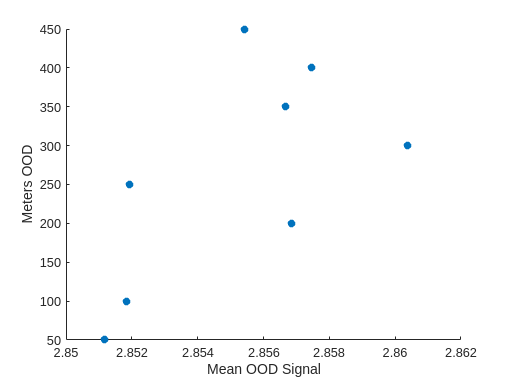

max_y_signal_450 = csv_450((csv_450.y >= 449.9),"signal");
max_signal_mean_450 = mean(max_y_signal_450);

max_means = [max_signal_mean_50{1, "signal"}, 
             max_signal_mean_100{1, "signal"}, 
             max_signal_mean_200{1, "signal"},
             max_signal_mean_250{1, "signal"},
             max_signal_mean_300{1, "signal"},
             max_signal_mean_350{1, "signal"},
             max_signal_mean_400{1, "signal"},
             max_signal_mean_450{1, "signal"}];
max_signals = [signal_50_max, 
               signal_100_max, 
               signal_200_max,
               signal_250_max,
               signal_300_max,
               signal_350_max,
               signal_400_max,
               signal_450_max];
OODs = [50, 100, 200, 250, 300, 350, 400, 450];

scatter(max_means, OODs, "filled");
hold on;
xlabel("Mean OOD Signal");
ylabel("Meters OOD");
hold off;

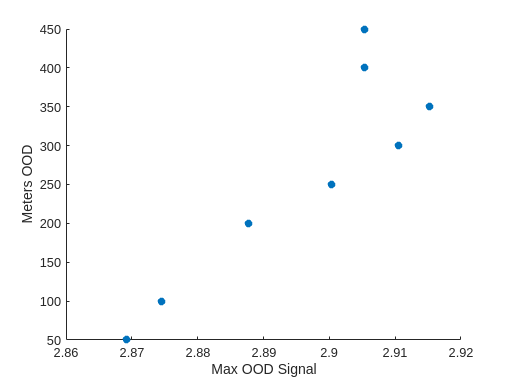


scatter(max_signals, OODs, "filled");
hold on;
xlabel("Max OOD Signal");
ylabel("Meters OOD");
hold off;

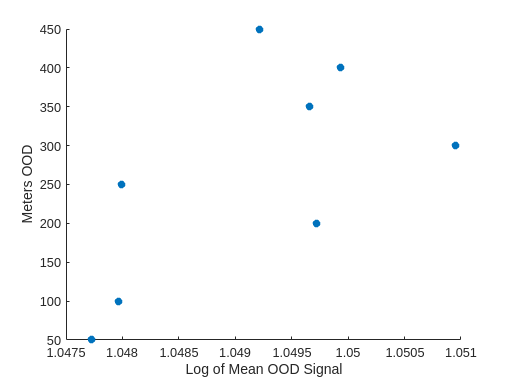


scatter(log(max_means), OODs, "filled");
hold on;
xlabel("Log of Mean OOD Signal");
ylabel("Meters OOD");
hold off;


% scatter(signal_50_squished, y_50_squished);
% hold on;
% title("50 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;
% 
% scatter(signal_100_squished, y_100_squished);
% hold on;
% title("100 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;
% 
% scatter(signal_200_squished, y_200_squished);
% hold on;
% title("200 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;
% 
% scatter(signal_250_squished, y_250_squished);
% hold on;
% title("250 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;
% 
% scatter(signal_300_squished, y_300_squished);
% hold on;
% title("300 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;
% 
% scatter(signal_350_squished, y_350_squished);
% hold on;
% title("350 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;
% 
% scatter(signal_400_squished, y_400_squished);
% hold on;
% title("400 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;
% 
% scatter(signal_450_squished, y_450_squished);
% hold on;
% title("450 Meters OOD")
% xlabel('OOD Signal');
% ylabel('Crosstrack Error');
% hold off;


% scatter3(fifty, signal_50_squished, y_50_squished, "cyan");
% hold on;
% scatter3(hundred, signal_100_squished, y_100_squished, "red");
% scatter3(twohun, signal_200_squished, y_200_squished, "blue");
% scatter3(twohunfif, signal_250_squished, y_250_squished, "green");
% scatter3(threehund, signal_300_squished, y_300_squished, "magenta");
% scatter3(threehunfif, signal_350_squished, y_350_squished, "yellow");
% scatter3(fourhund, signal_400_squished, y_400_squished, "black");
% scatter3(fourhunfif, signal_450_squished, y_450_squished);
% hold off;




